## preparations

close all;
clc;

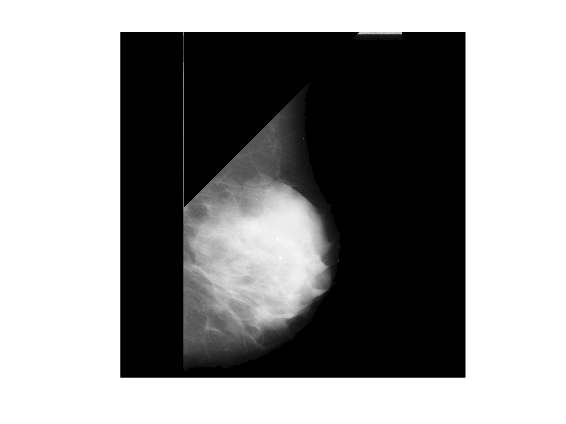

clear all;


% Sample data
%texture = load('C:\Program Files\MATLAB\R2023a\toolbox\images\imdata\cell.tif');
%f = texture.f;
r=imread('.\data\DATA_MIAS_PECTORAL_REMOVE\mdb_pr002.pgm');
figure('Name', 'Input image');
imagesc(r);
colormap gray;
axis equal;
axis off;

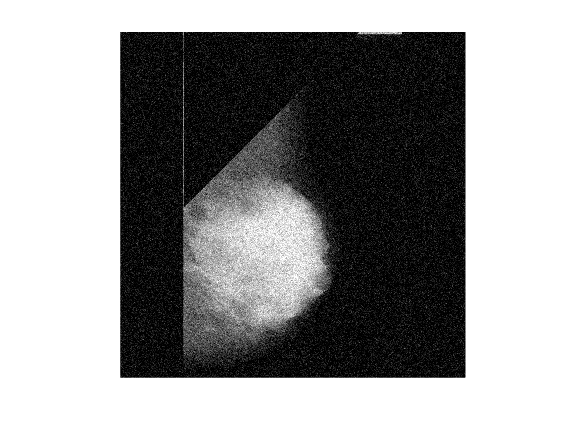


f = imnoise(r,'gaussian',0.01); % coi lai variant
figure('Name', 'Noise image');
imagesc(f);
colormap gray;
axis equal;
axis off;

### Step 1

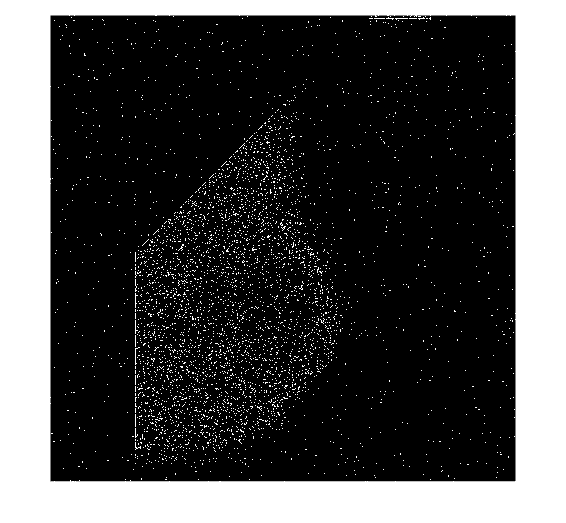

filteredSobel  = edge(f,"Sobel");
figure('Name', 'Sobel image');
imshow(mat2gray(filteredSobel));
axis equal;
axis off;

filteredSobel = double(filteredSobel);
% mat2gray

### Step 2

% parameters:
alpha = 5000;       % bandwidth constraint
tau = 0.25;         % Lagrangian multipliers dual ascent time step
K = 4;              % number of modes
DC = 1;             % includes DC part (first mode at DC)

init = 1;           % initialize omegas randomly, may need multiple runs!

tol = K*10^-6;      % tolerance (for convergence)
[u, u_hat, omega] = VMD_2D(f, alpha, tau, K, DC, init, tol);

Me0 = adapthisteq(u(:,:,1));

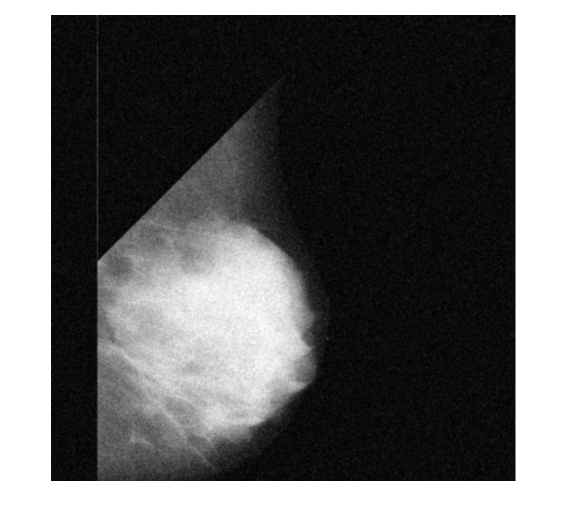

figure("Name","M0");
imshow(mat2gray(u(:,:,1)));

### Step 3

Pkm = zeros(size(u(:,:,1)));
for k=2:K
     mf=medfilt2(u(:,:,k));
     Pkm = Pkm + mf;
end

alpha = 0;
beta = 0.7;
gamma = 0.3;
r = uint8(r);
Yd = alpha*Me0 + beta*filteredSobel + gamma*Pkm;
Y = uint8(Yd);
disp(["MI=",mi(r,Y)]);

    "MI="    "0.0196"



disp(["RMSE=",sqrt(mean((r(:)-Y(:)).^2))]);

    "RMSE="    "7.8526"



disp(["PSNR=",psnr(Y,r)]);

    "PSNR="    "11.2986"



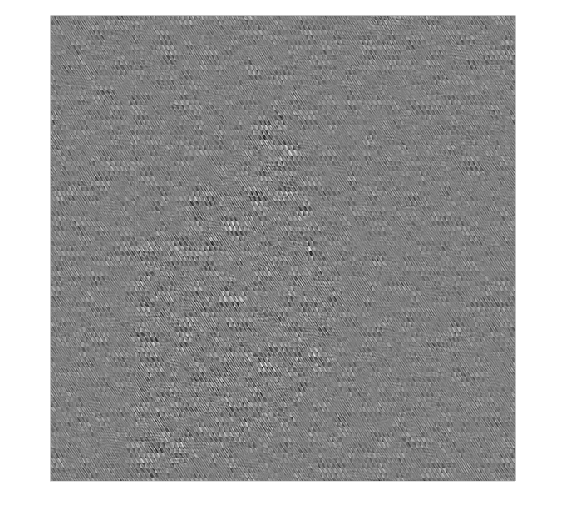

figure('Name', 'Output image');
imshow(mat2gray(Yd));
axis equal;
axis off;

% mi(f,Y)

% alpharange = 0.1:0.01:1
% mia = zeros(1,length(alpharange));
% rmsea = zeros(1,length(alpharange));
% for i = 1:length(alpharange)
%     alpha = alpharange(i);
%     beta = 0.5;
%     gamma = 0.5;
%     Y = alpha*Me0 + beta*filteredSobel + gamma*Pkm;
%     mia(i) = mi(f,Y);
%     rmsea(i) = sqrt(mean((f(:)-Y(:)).^2));
% end

% figure('Name',"mivsalpha");
% plot(alpharange,mia);
% figure('Name',"rmsevsalpha");
% plot(alpharange,rmsea);

## Visualization

% figure('Name', 'Input image');
% imagesc(f);
% colormap gray;
% axis equal;
% axis off;
% 
% figure('Name', 'Input spectrum');
% imagesc(abs(fftshift(fft2(f))));
% colormap gray;
% axis equal;
% axis off;
% hold on;
% colors = 'rbycmg';
% if(size(omega,3)>length(colors))
%     for i=1:ceil(size(omega,3)/length(colors))
%         colors = strcat(colors,'rbycmg');
%     end
% end
% for k = 1:size(omega,3)
%     plot( size(f,2)*(0.5+omega(:,1,k)), size(f,1)*(0.5+omega(:,2,k)), colors(k) );
% end
% 
% for k=1:size(u,3)
%     figure('Name', ['Mode #' num2str(k)]);
%     imagesc(u(:,:,k));
%     colormap gray;
%     axis equal;
%     axis off;
% end
% 
% figure('Name', 'Reconstructed composite');
% imagesc(sum(u,3));
% colormap gray;
% axis equal;
% axis off;